# **Lab 01**

## Welcome to the first Lab sesion. This Lab Tutorial provides an introductionary overview of Matlab:

**Operators:**

-  +, -    addition and subtraction

- *, /, \   multiplication and division

- -         negation

- ^        exponentiation

% Four basic opperation:
a = 20
b = 10;

% addition
addition = a + b

% subtraction
subtraction = a - b

% multiplication
multiplication = a *b

% division
division1 = a / b
division2 = a \ b

 


**The format of displaying numbers:**

% Long format
format long
2 * sin(1.6)

ans =    1.999147206083010



% Short format (the default)
format short
2 * sin(1.6)

ans = 1.9991

**Constants:**

- pi         3.14159

- i           square root of -1

- NaN     not a number

pi

ans = 3.1416

i^2

ans = -1

N = NaN

N = NaN

**Chracters and strings:**

var = 5

var = 5

char = '5'

char = '5'

str = 'Hello world!'

str = 'Hello world!'

**Relational Operators:**

- >      greater than

- <      less than

- >=    greater than or equals

- >=    less than or equals

- ==    equality

- ~=    inequality

3 < 7
5 > 10

 

**Logical Operators:**

- ||       or

- &&    and

- ~      not

2 > 4 || 1 ~= 2 

 

**Input and output functions: **

output:

disp('This is a test for disp function')
disp(2*5)

fprintf('Hello: %d', 17)
%  %d integer
%  %f float
%  %c character
%  %s string

 

Input: 

newvar = input('Please insert your number: ')
disp(newvar)

 

**Verctor and Matrices:**

Creating row vectors:

v1 = [1 2 3 4 5]
v2 = [1, 2, 3, 4, 5]

 

Colon operator and linspace function:

% colon
v3 = 5:11

v3 =      5     6     7     8     9    10    11


v4 = 5:2:11

v4 =      5     7     9    11



% linspace
v5 = linspace(5, 11, 3)

v5 =      5     8    11


v6 = v5' % Transpose

v6 =      5
     8
    11



v3(1)

ans = 5

v3(2:3)

ans =      6     7


v3(end) % v3(4)

ans = 11

Creating Matrix:

m1 = [1, 2, 3; 4, 5, 6]
m2 = [1, 2, 3
      4, 5, 6
      7, 8, 9]

m1 (1, 2)
m2(1:2, 2:3)

 

Vector and matrix modification:

m4 = ones(1, 5)
m4(1:3) = -1

m5 = zeros(2, 3)
m5(1, 3) = 5

 

Dimensions:

[Nrow, Ncolumn] = size(m5)

l1 = length(m4)

l2 = length(m5)

ne = numel(m5)

 

Martix and vector operations:

v4 = 2 * ones(1, 5)
size(v4)

v5 = 3 * ones(5, 1)
size(v5)

v6 = v4 + 2
size(v6)

v7 = v4 .* v6
v8 = v4 ./ v6

v9 = [v7
      v8]

v10 = v9 * v5

 

**Selection statements:**

"if" statement:

if condition

    action

elseif condition

    action

else 

    action

end

if (2<10)
    disp('2 is less than 10.')
end

2 is less than 10.




if rand < 0.3
    disp('It was less than 0.3.')
elseif 0.3 <= rand <= 0.7
    disp('It was between 0.3 and 0.7.')
else
    disp('It was greater than 0.7.')
end

It was less than 0.3.


**Loop statements:**

"for" loop:

for loopvar = range

    action

end

for i=1:3
    disp(i*2)
end

     2

     4

     6



"while" loop:

while condition

    action

end

num = 5;
while num>=0
    disp(num)
    num = num - 1;
end

     5

     4

     3

     2

     1

     0



**Loading and saving data:**

save data:

variable1 = 12;
variable2 = [1, 2, 3; 4, 5, 6];
disp(variable1)
disp(variable2)

save Lab01_Data.mat variable1 variable2

 

load data:

clc
clear all

load Lab01_Data.mat

disp(variable1)
disp(variable2)

 

** ploting:**

2D plot:

t = linspace(0, 3, 100);
y = 2 * sin(2*pi*t);

plot(t, y)
xlabel('time')
ylabel('amplitude')

 

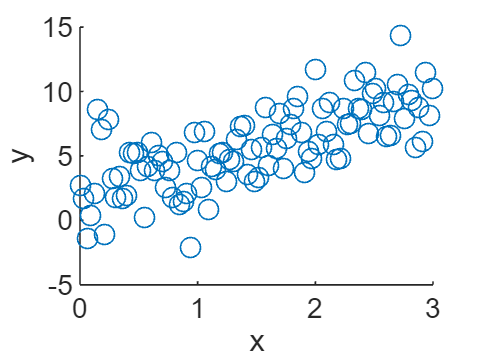

x = linspace(0, 3, 100);
y = 3 * x + 1 + 2*randn(1, 100);

scatter(x, y)
xlabel('x')
ylabel('y')

3D plot:

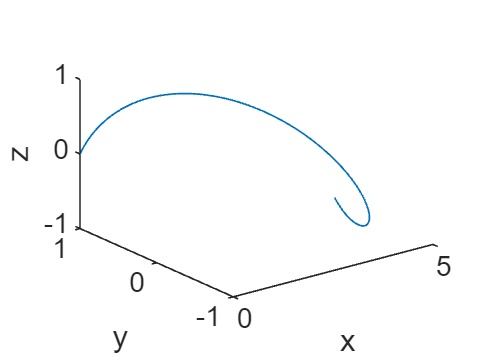

x= linspace(0, 5, 100);
y = cos(x);

z = sin(x);

plot3(x,y,z)
xlabel('x')
ylabel('y')
zlabel('z')

**Curve Fitting:**

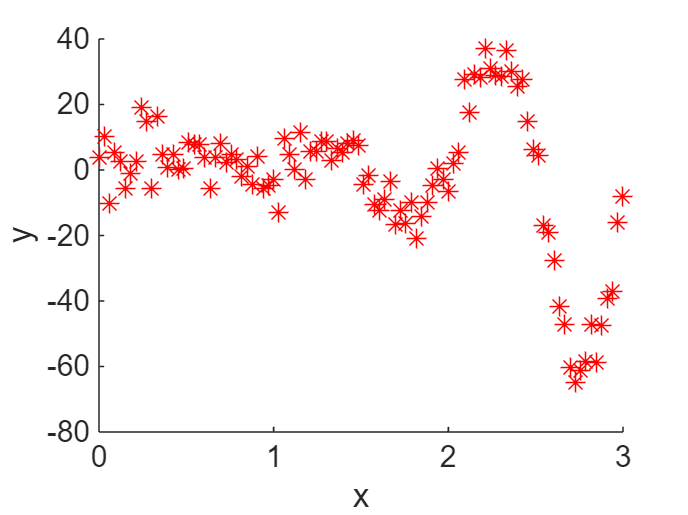

% creating data
x = linspace(0, 3, 100);
y = (3 * x.^3 .* sin(2*pi*x)+ 1 + 5*randn(1, 100));

% ploting data
scatter(x, y, 'r*')
xlabel('x')
ylabel('y')

Linear fitting:

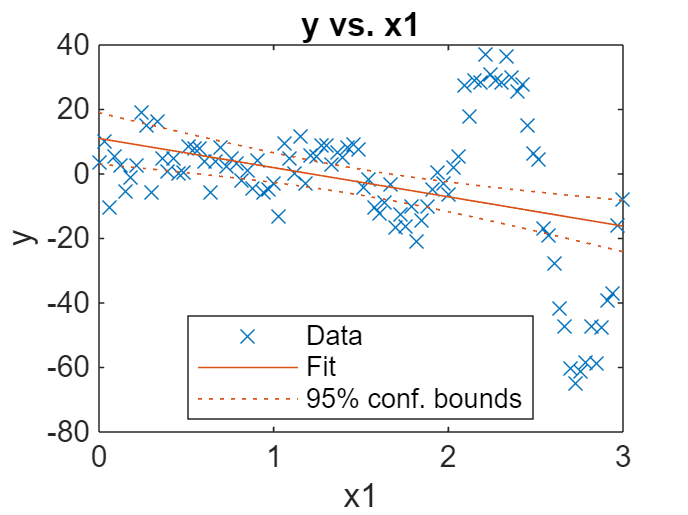

% pridicting with linear model
FitModel01 = LinearModel.fit(x, y);
plot(FitModel01)

Nonlinear fitting:

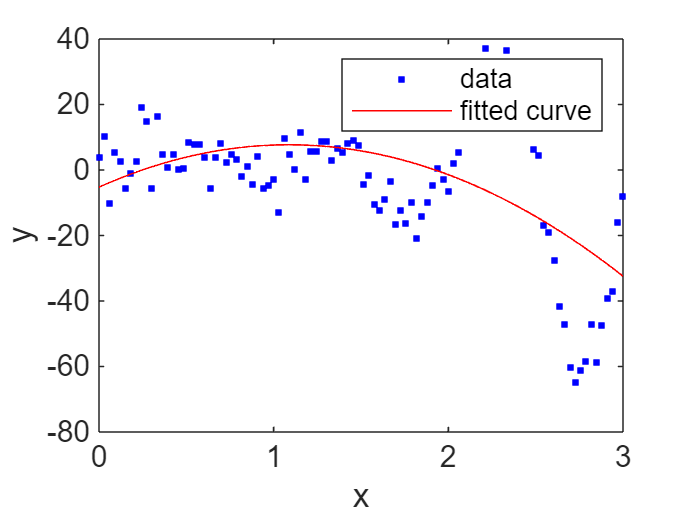

% pridicting with non-linear model
x = x';
y = y';
FitModel02 = fit(x, y, 'poly2');
plot(FitModel02, x, y)

LIF model:

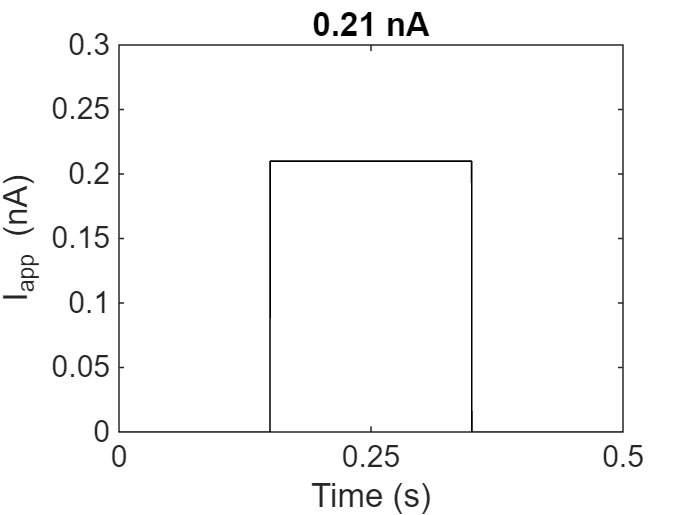

%% Simulating a Simple Neuron Model Using the Leaky Integrate-and-Fire Model
% This tutorial will guide you through simulating a simple neuron using the
% leaky integrate-and-fire (LIF) model. The LIF model is a basic model of
% neuron dynamics, where the membrane potential is governed by the balance
% of incoming currents and leaks through the membrane.

%% Step 1: Initialize Parameters
% First, let's define all the necessary parameters for our simulation.

% Time-step for the simulation (in seconds)
dt = 0.0001;

% Vector of time-points (from 0 to 0.5 seconds)
t = 0:dt:0.5;

% Time to begin applied current (onset) in seconds
ton = 0.15;

% Time to end applied current (offset) in seconds
toff = 0.35;

% Membrane time constant (tau) in seconds
tau = 0.010;

% Leak potential (also known as resting potential) in volts
E_L = -0.070;

% Threshold potential in volts (the potential at which a spike is generated)
Vth = -0.050;

% Reset potential in volts (the potential after a spike)
Vreset = -0.080;

% Total membrane capacitance in farads
Cm = 100e-12;

% Total membrane conductance (leak conductance) in siemens
G_L = Cm / tau;

% Value of applied current steps in amperes
Iapp = 210e-12;

%% Step 2: Create Time-Dependent Variables
% We will now create the time-dependent variables such as the applied current
% and the membrane potential.

% Vector for current at each time-point (initialized to zero)
I = zeros(size(t));

% Indices for current onset and offset
non = round(ton / dt);
noff = round(toff / dt);

% Add the applied current between 'ton' and 'toff'
I(non:noff) = Iapp;

% Initialize the membrane potential vector with the resting potential
V = E_L * ones(size(t));

% Initialize a vector to record spikes (0 means no spike, 1 means spike)
spikes = zeros(size(t));

%% Step 3: Simulate the Neuron Dynamics
% We will now simulate the neuron dynamics using a for loop to iterate through
% each time-point. The membrane potential is updated using the Forward Euler method.

for i = 2:length(t)
    % Update membrane potential using Forward Euler method
    V(i) = V(i-1) + dt * (I(i) + G_L * (E_L - V(i-1))) / Cm;
    
    % Check if the membrane potential exceeds the threshold potential
    if V(i) > Vth
        % Record the spike
        spikes(i) = 1;
        
        % Reset the potential after the spike
        V(i) = Vreset;
    end
end

%% Step 4: Plot the Applied Current
% Let's plot the applied current over time. This will help us visualize when
% the current was applied to the neuron.

figure(1)
plot(t, I * 1e9, 'k'); % Convert current to nanoamperes for plotting
ylabel('I_{app} (nA)')
title(strcat(num2str(1e9 * Iapp), ' nA')) % Add a title with the current value
xlabel('Time (s)')
set(gca, 'XTick', [0 0.25 0.5])
axis([0 0.5 0 0.3]) % Set x-axis and y-axis ranges

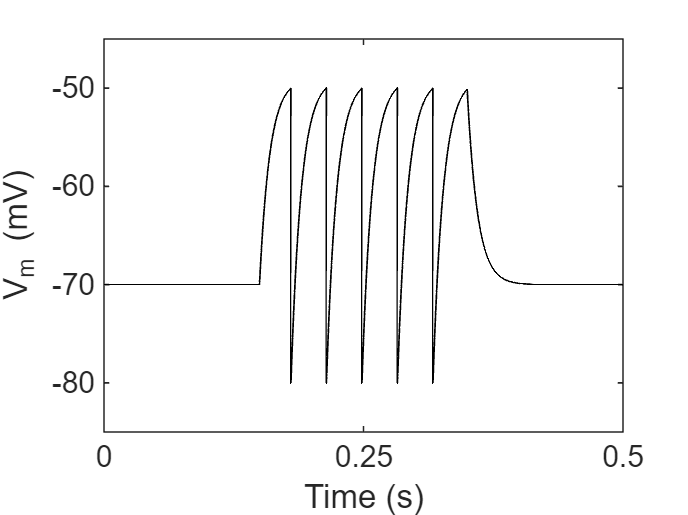


%% Step 5: Plot the Membrane Potential
% Next, we'll plot the membrane potential over time to observe how the neuron
% responds to the applied current.

figure(2)
plot(t, 1000 * V, 'k'); % Convert potential to millivolts for plotting
ylabel('V_m (mV)')
xlabel('Time (s)')
set(gca, 'XTick', [0 0.25 0.5])
axis([0 0.5 1000 * (Vreset - 0.005) 1000 * (Vth + 0.005)]) % Set axes limits

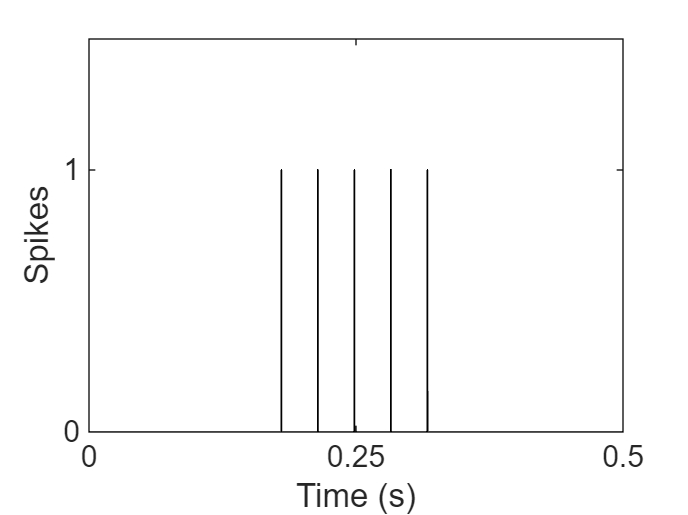


%% Step 6: Plot the Spikes
% Finally, let's plot the spikes. This plot shows when the neuron generated
% an action potential.

figure(3)
plot(t, spikes, 'k') % Plot spikes
xlabel('Time (s)')
ylabel('Spikes')
set(gca, 'XTick', [0 0.25 0.5])
set(gca, 'YTick', [0 1])
axis([0 0.5 0 1]) % Set x-axis and y-axis ranges
ylim([0 1.5])

%% Conclusion
% In this tutorial, we simulated a neuron using the leaky integrate-and-fire
% model. We applied a current to the neuron, updated the membrane potential
% over time, and recorded spikes when the potential exceeded the threshold.
% The resulting plots give us insight into the behavior of the neuron in
% response to the applied current.

 